rect = @(t) double(abs(t) <= 0.5);
w =@(t) rect(t);

f_1 =@(t) sin(t)/t;
f_2 =@(t) exp(-3 * abs(t));

%For continous functions
function result=general_fourier_transform (f)
    result= @(omega) integral(@(t) f(t) .* exp(-1j * omega * t), -inf,inf, 'ArrayValued', true);
end

%For discrete or high oscillatory integrals (for example exp(-j*A(t))
function result=general_fourier_transform_discrete (f)
    t = linspace(-10, 10, 10000); 
    f_discrete = f(t);
    result= @(omega) trapz(t, f_discrete.* exp(-1j * omega * t));
end
omega = linspace(-20, 20, 1000);

%f1(t)*w(t)
result = arrayfun(general_fourier_transform(@(t) f_1(t)*w(t)) ,omega);
plot(omega,result);

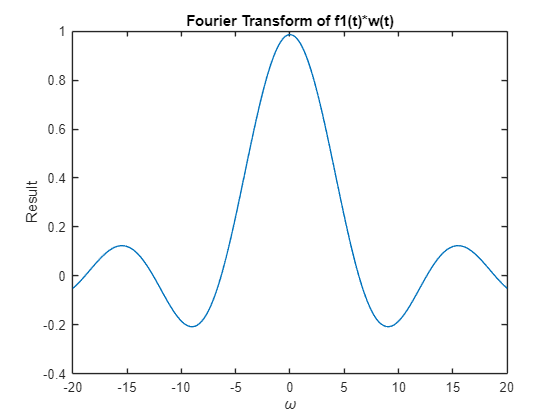

title('Fourier Transform of f1(t)*w(t)');
xlabel('\omega');
ylabel('Result');


%Conv (f1(t) * w(t))
F1_transform=arrayfun(general_fourier_transform_discrete(f_1),omega);
plot(omega,F1_transform);

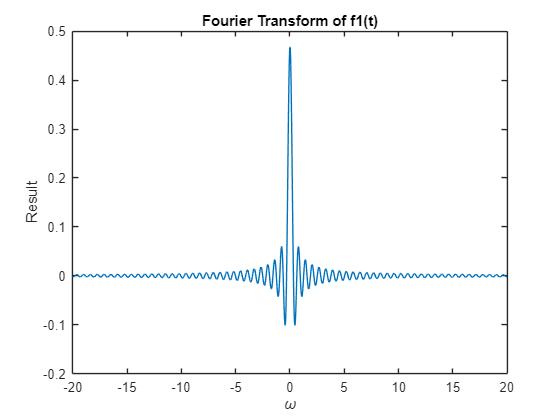

title('Fourier Transform of f1(t)');
xlabel('\omega');
ylabel('Result');

W_transform=arrayfun(general_fourier_transform(w),omega);
plot(omega,W_transform);

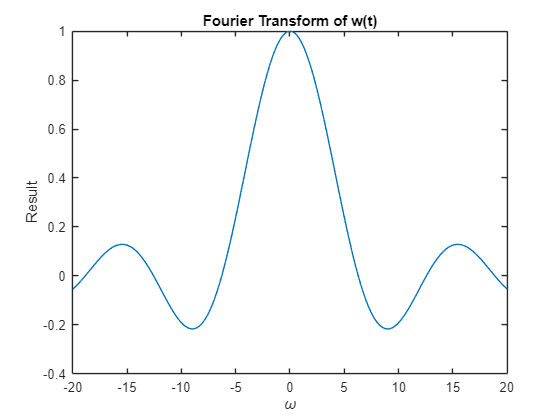

title('Fourier Transform of w(t)');
xlabel('\omega');
ylabel('Result');

plot(omega,conv(F1_transform ,W_transform,'same'))

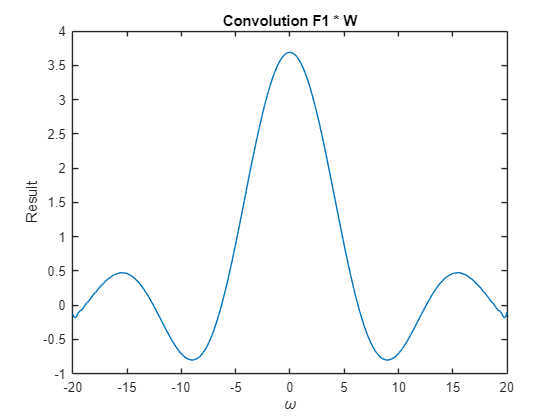

title('Convolution F1 * W');
xlabel('\omega');
ylabel('Result');



%f2(t)*w(t)
result = arrayfun(general_fourier_transform(@(t) f_2(t)*w(t)) ,omega);
plot(omega,result);

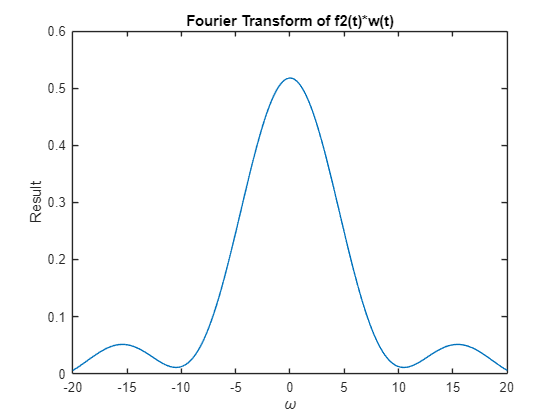

title('Fourier Transform of f2(t)*w(t)');
xlabel('\omega');
ylabel('Result');


%Conv (f2(t) * w(t))
F2_transform=arrayfun(general_fourier_transform_discrete(f_2),omega);
plot(omega,F2_transform);

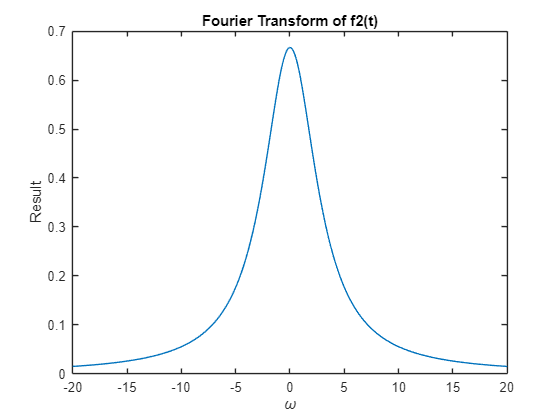

title('Fourier Transform of f2(t)');
xlabel('\omega');
ylabel('Result');

plot(omega,conv(F2_transform ,W_transform,'same'))

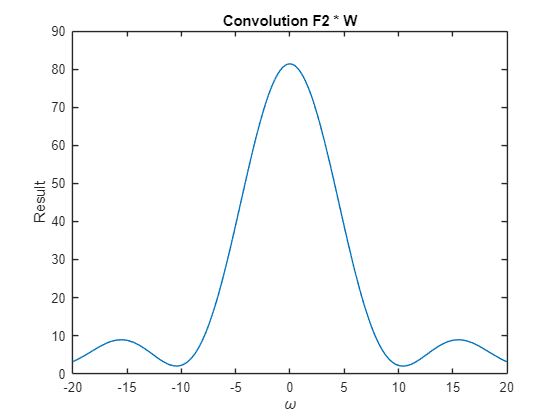

title('Convolution F2 * W');
xlabel('\omega');
ylabel('Result');